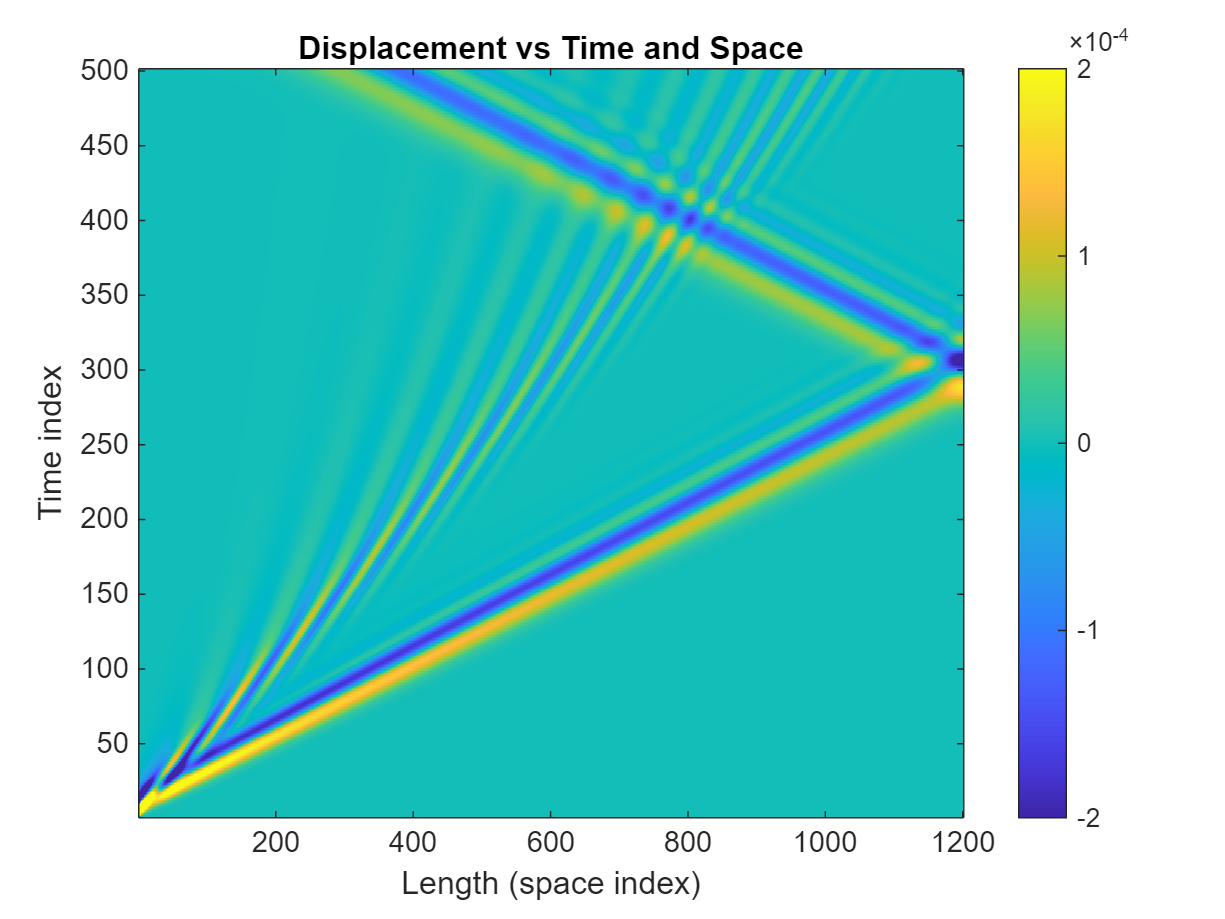

clear
load simout.mat
simout=simout(2:end,:);
t=simout(:,1);
out=simout(:,2:2:end);
% we have a 'out' matrix that is 501x1201. 501 is time and 1201 is lenghts
% and the value in each cell is displacement in time in space write matlab
% code to plot this
out=table2array(out);
% out is 501 x 1201 (time x space)

figure
imagesc(out)
axis xy
colorbar
clim([-2,2]/1e4)
xlabel('Length (space index)')
ylabel('Time index')
title('Displacement vs Time and Space')

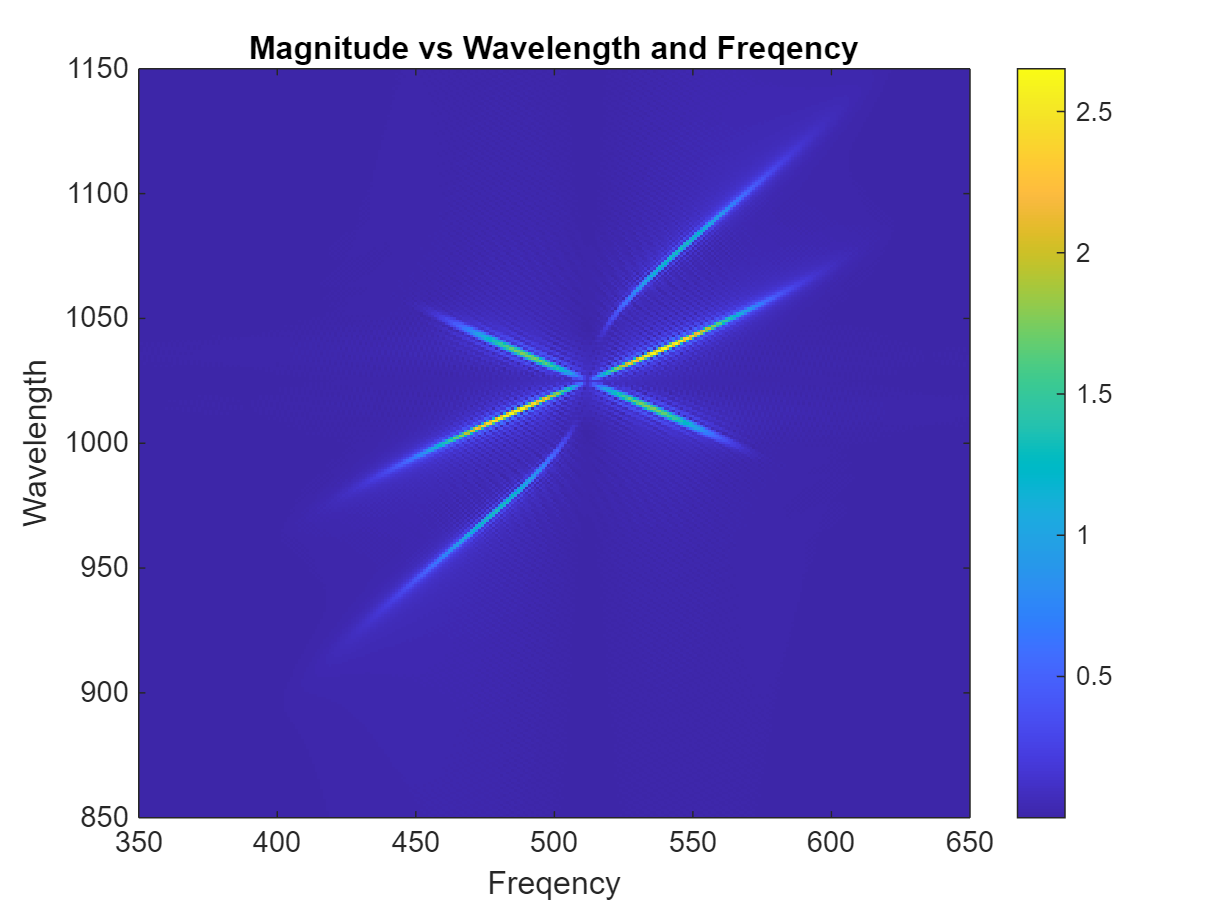


X=flip(fft2(out,2^10,2^11)',2);
% X=flip(fft2(out,2^9,2^10)',2);
X=fftshift(X);

figure
imagesc(abs(X))
axis xy
colorbar
xlim([350,650]);
ylim([850,1150]);
xlabel('Freqency')
ylabel('Wavelength')
title('Magnitude vs Wavelength and Freqency')

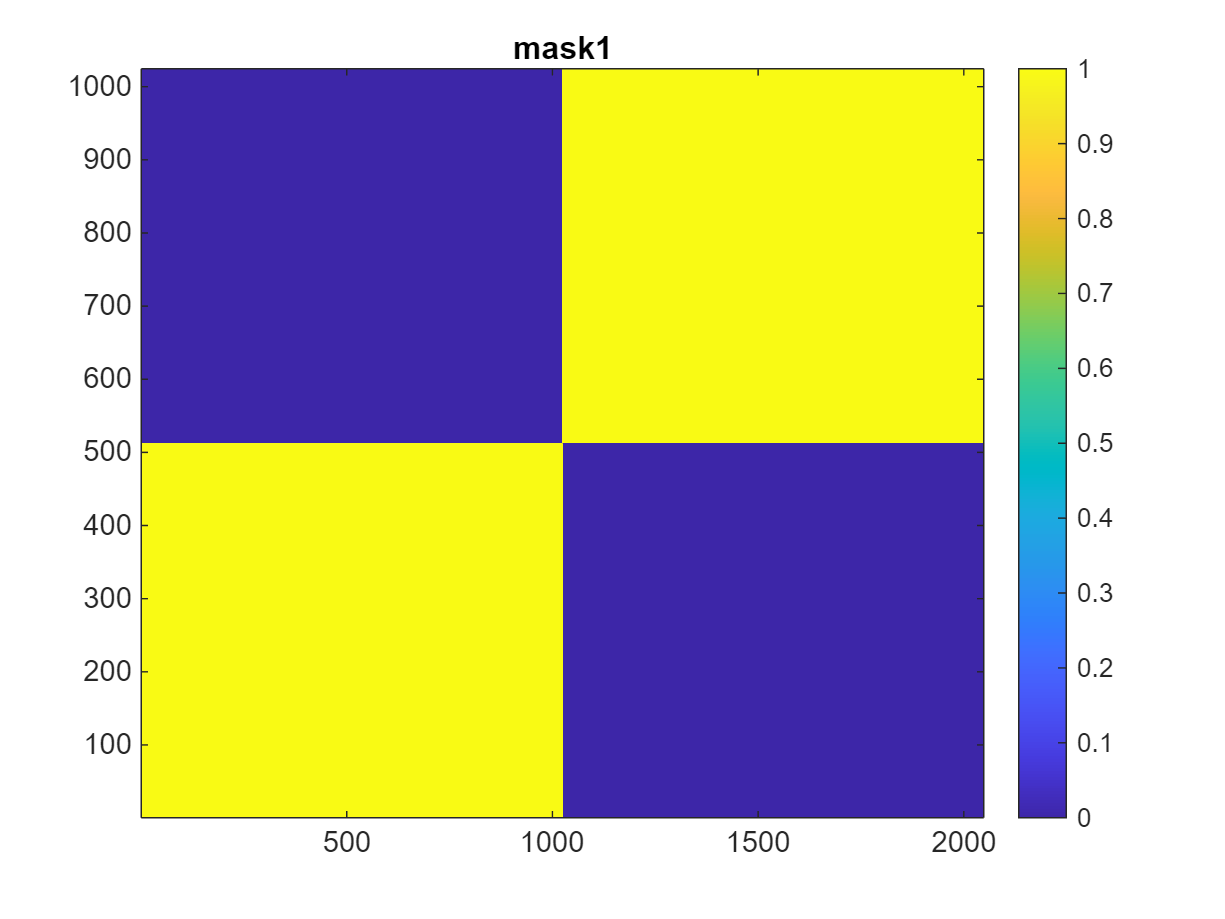


one=ones(2^9,2^10);
zero=zeros(2^9,2^10);
% one=ones(2^8,2^9);
% zero=zeros(2^8,2^9);
mask=[one,zero;zero,one];
mask2=[zero,one;one,zero];

figure
imagesc(mask)
title('mask1')
axis xy
colorbar

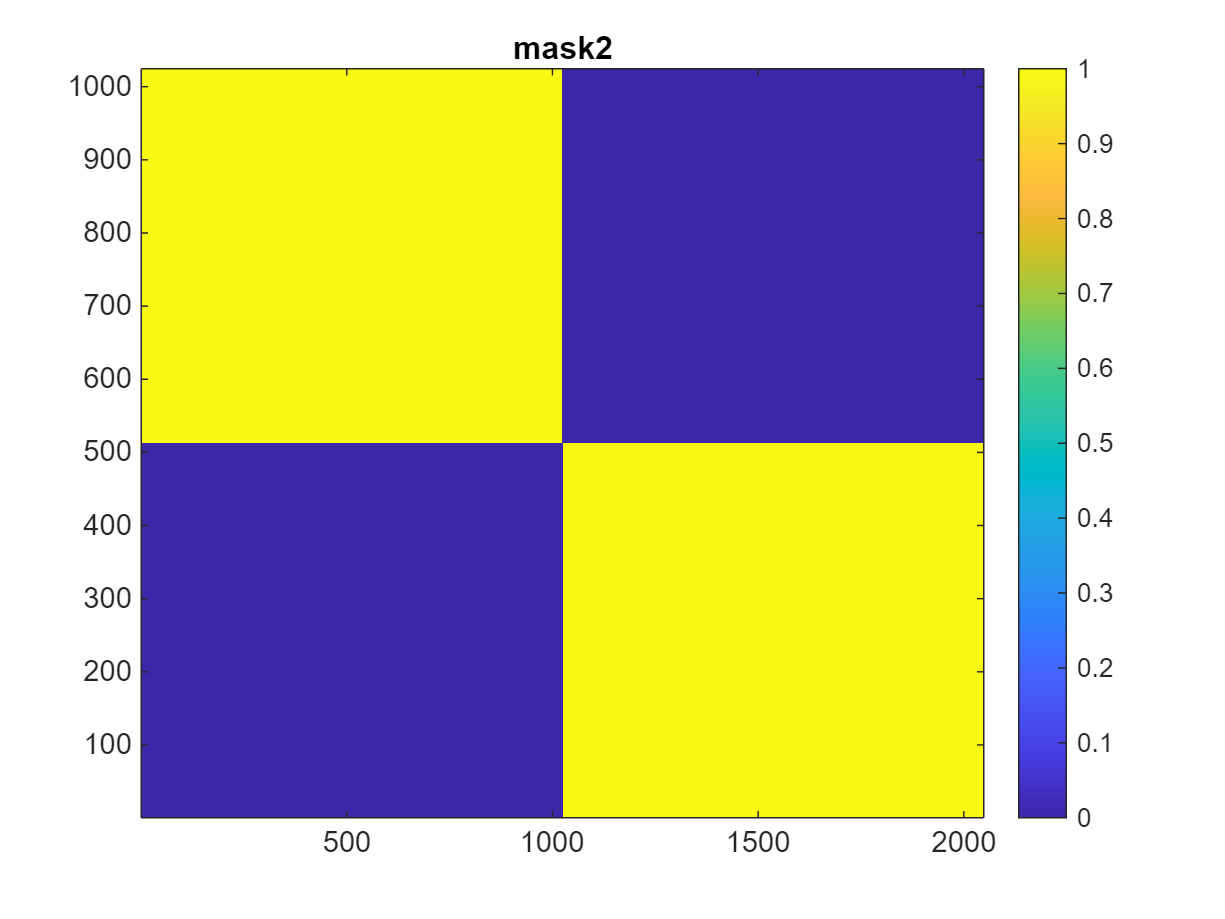

figure
imagesc(mask2)
title('mask2')
axis xy
colorbar

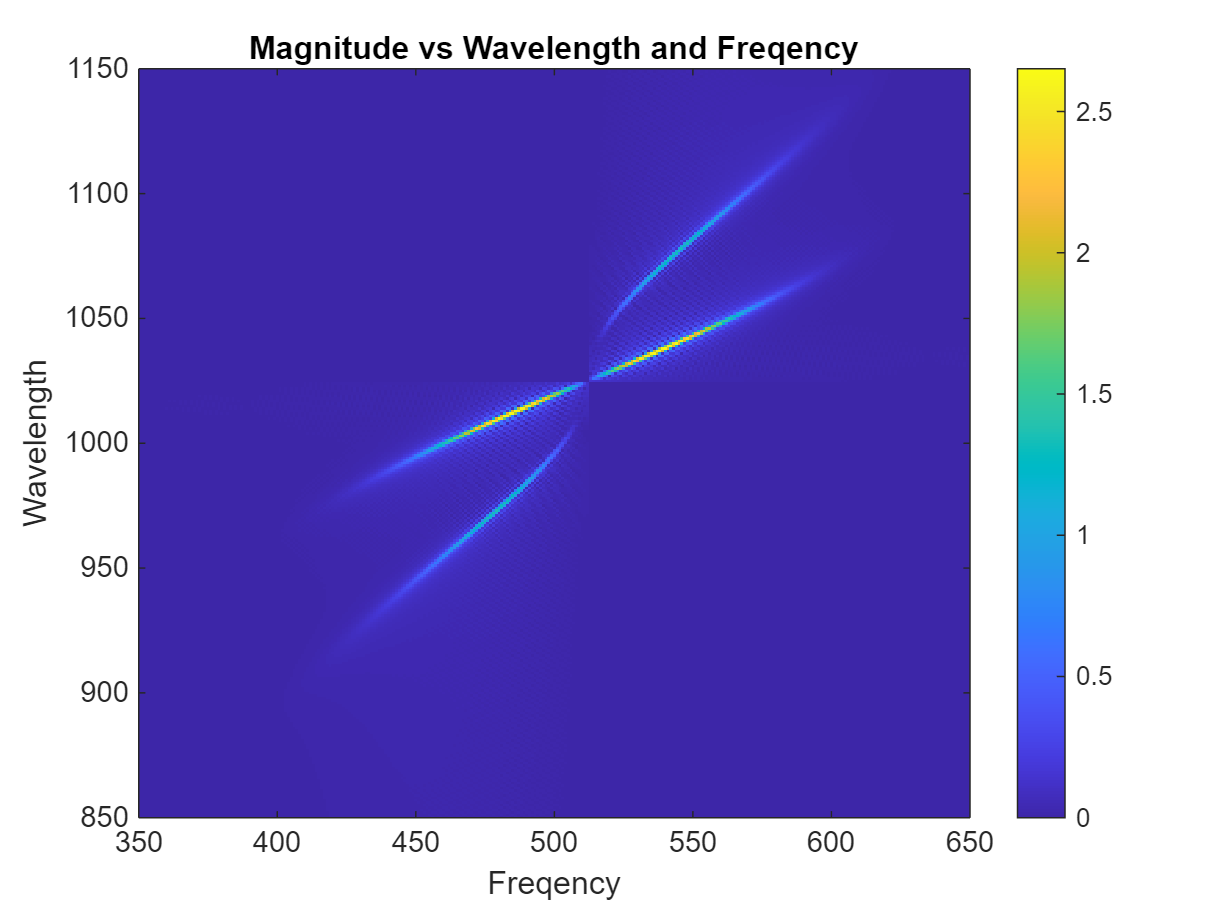



ans1=X.*mask';
ans2=X.*mask2';

figure
imagesc(abs(ans1))
axis xy
colorbar
xlim([350,650]);
ylim([850,1150]);
xlabel('Freqency')
ylabel('Wavelength')
title('Magnitude vs Wavelength and Freqency')

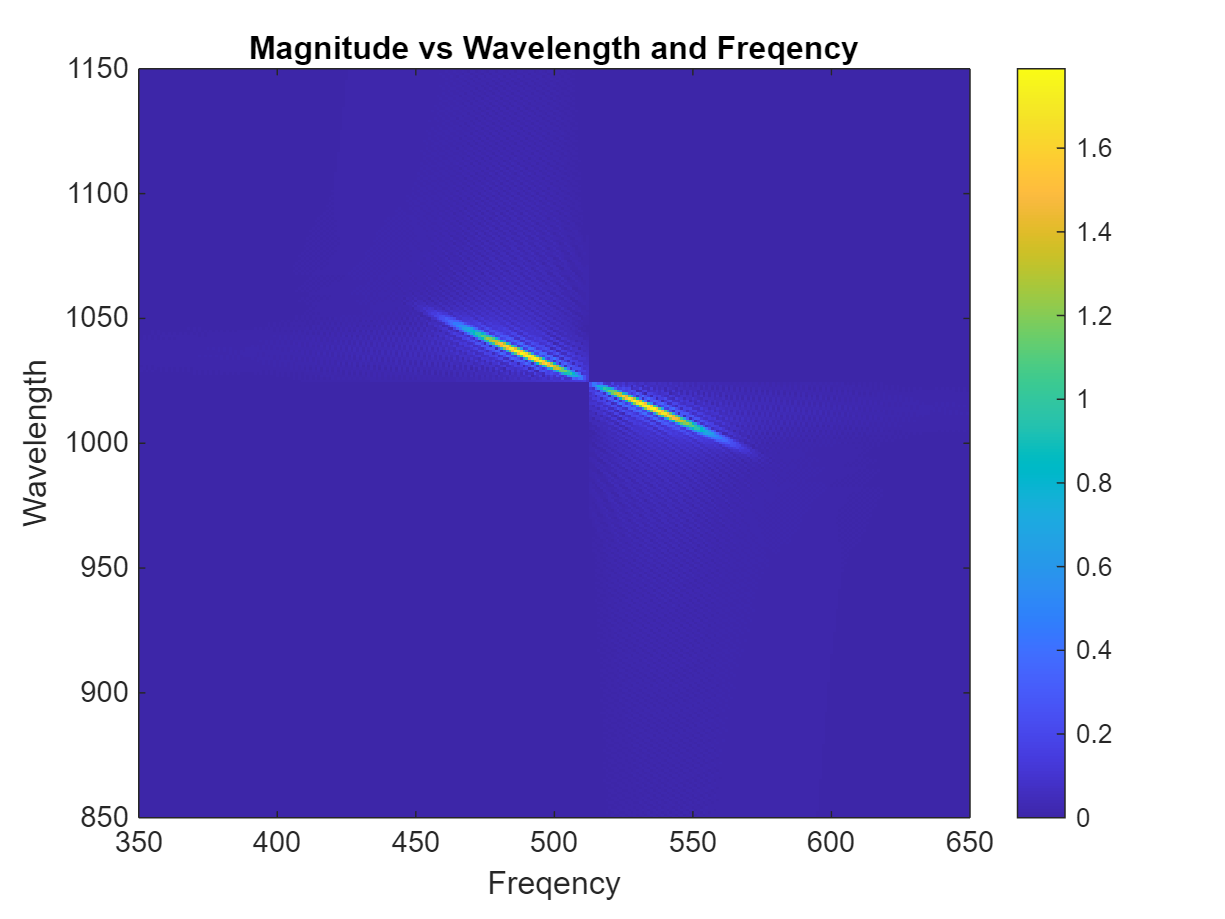


figure
imagesc(abs(ans2))
axis xy
colorbar
xlim([350,650]);
ylim([850,1150]);
xlabel('Freqency')
ylabel('Wavelength')
title('Magnitude vs Wavelength and Freqency')

X_inv = ifftshift(ans1);   %
X_inv = flip(X_inv, 2);
X_inv = X_inv.';
u_rec = ifft2(X_inv);

X_inv2 = ifftshift(ans2);   %
X_inv2 = flip(X_inv2, 2);
X_inv2 = X_inv2.';
u_rec2 = ifft2(X_inv2);

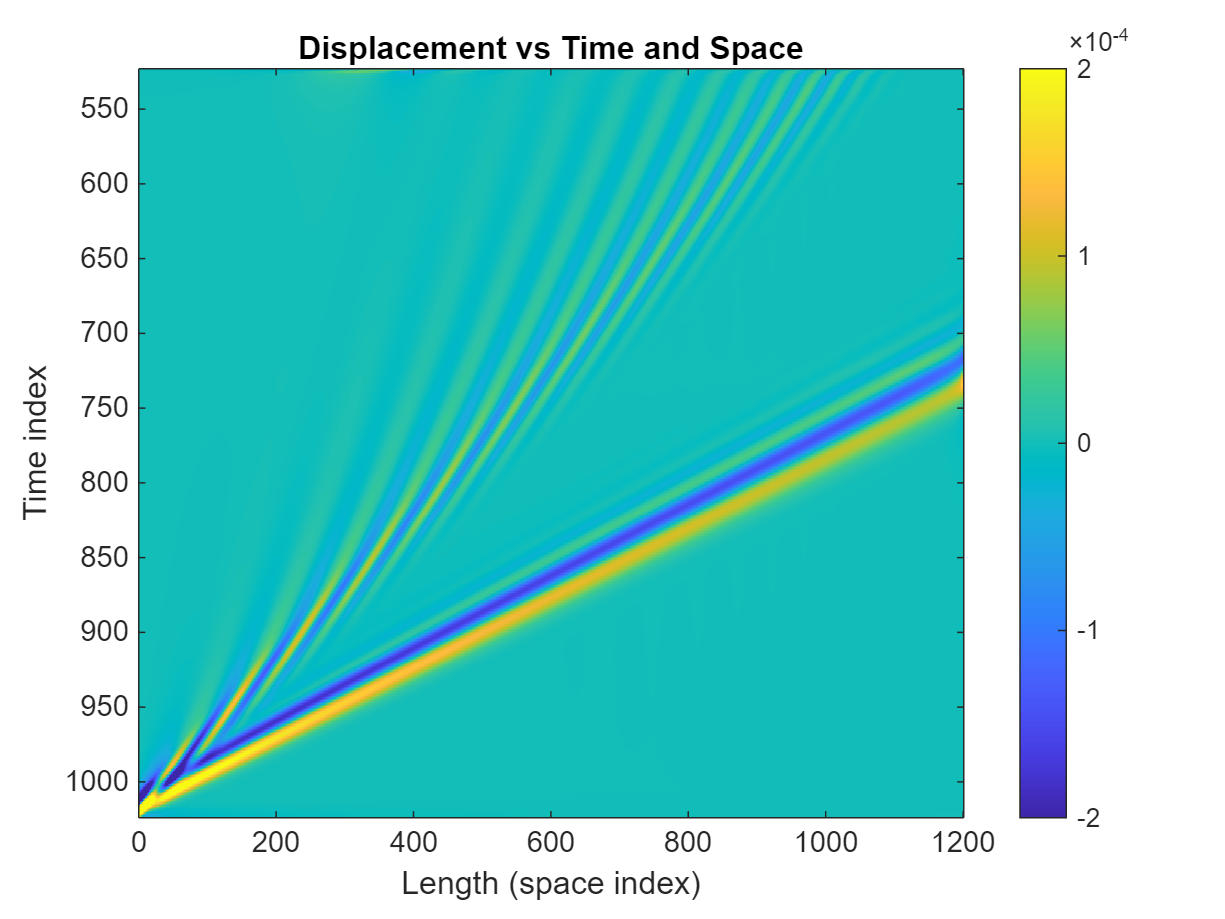

figure
imagesc(flip(real(u_rec),2))
% axis xy
colorbar
clim([-2,2]/1e4)
xlim([0,1201])
ylim([1024-501,1024])
xlabel('Length (space index)')
ylabel('Time index')
title('Displacement vs Time and Space')

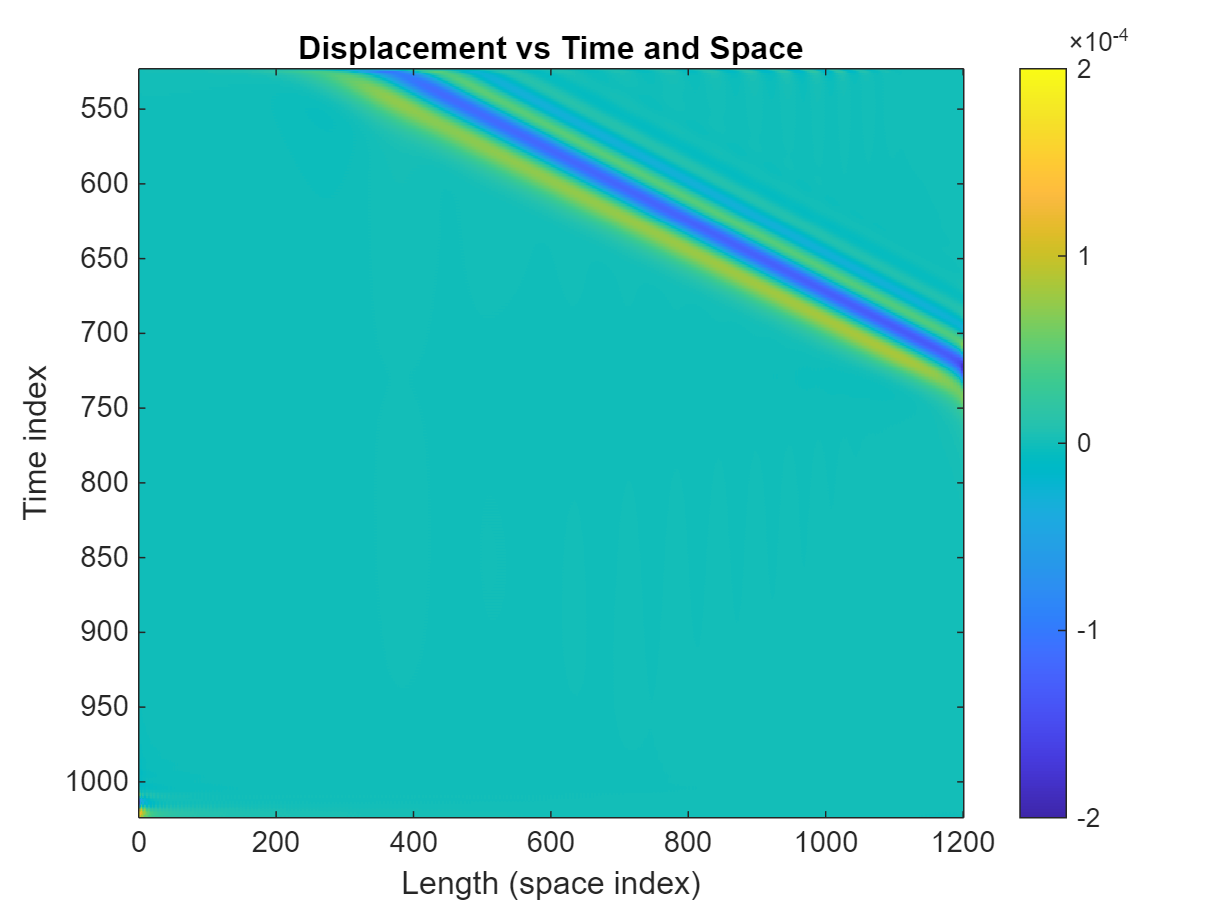



figure
imagesc(flip(real(u_rec2),2))
% axis xy
colorbar
clim([-2,2]/1e4)
xlim([0,1201])
ylim([1024-501,1024])
xlabel('Length (space index)')
ylabel('Time index')
title('Displacement vs Time and Space')


%u can see that in fft i zeropadded the signal. When coming back to time
%domain I want to go back to the original size before inverse fourriere
%transform. How t odo tat without loosing any info:

temp=flip(real(u_rec2),2);
temp2=temp(1:501,1:1201);
test=out-temp2;

figure
imagesc(temp)
xlim([0,1201])
ylim([1024-501,1024])
colorbar
clim([-2,2]/1e4)
xlabel('Length (space index)')
ylabel('Time index')
title('Displacement vs Time and Space')

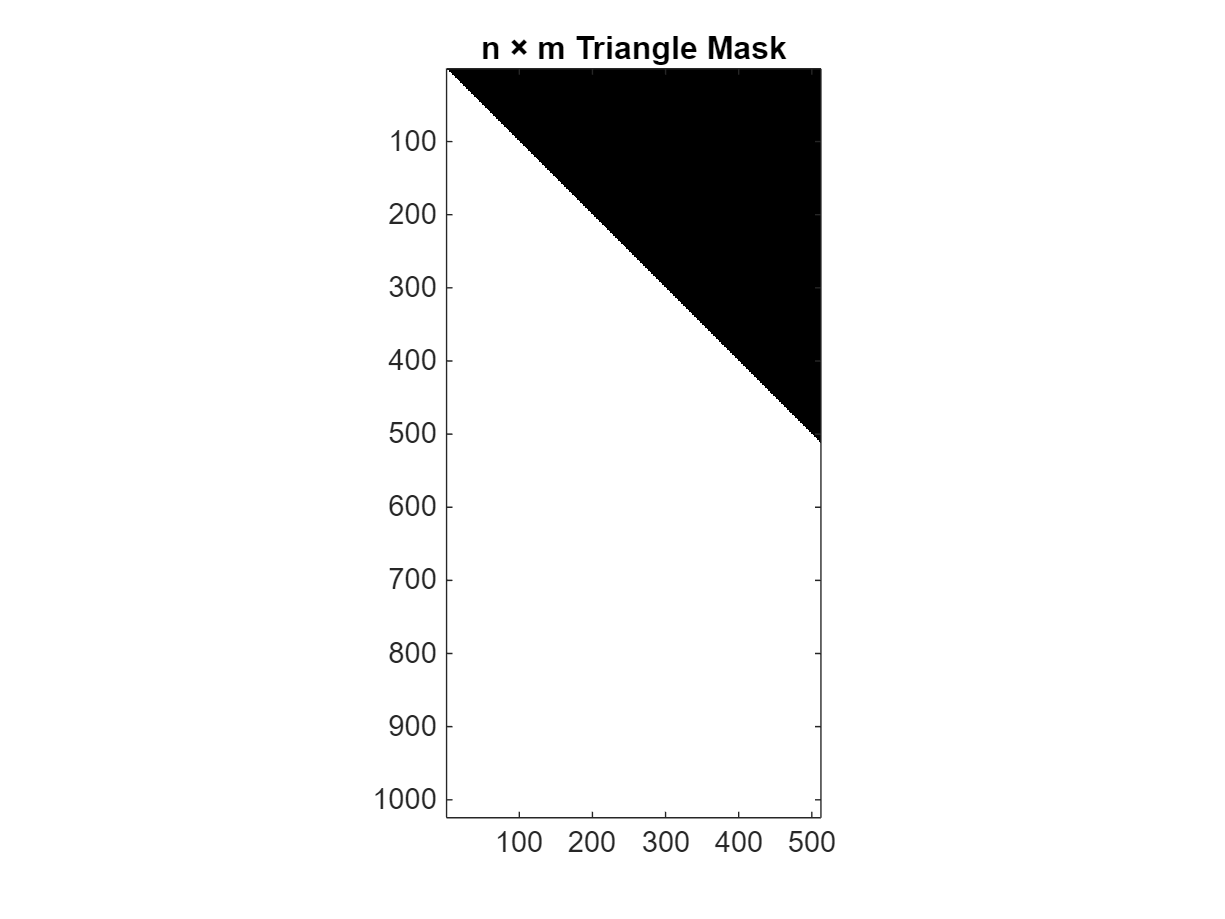

n = 2^11/2;
m= 2^10/2;
        % number of rows (height, y-direction)
        % number of columns (width, x-direction)
alpha = 45;     % angle in degrees

% Coordinate grid
[x, y] = meshgrid(1:m, 1:n);

% Move origin to bottom-left corner
Xp = x - 1;
Y = y - 1;

% Convert angle
alpha_rad = deg2rad(alpha);

% Triangle condition
inside_triangle = ...
    (Xp >= 0) & ...
    (Y >= 0) & ...
    (Y <= Xp * tan(alpha_rad));

% Create mask
M = ones(n, m);
M(inside_triangle) = 0;

% Display
imagesc(M)
axis equal tight
colormap(gray)
title('n × m Triangle Mask')

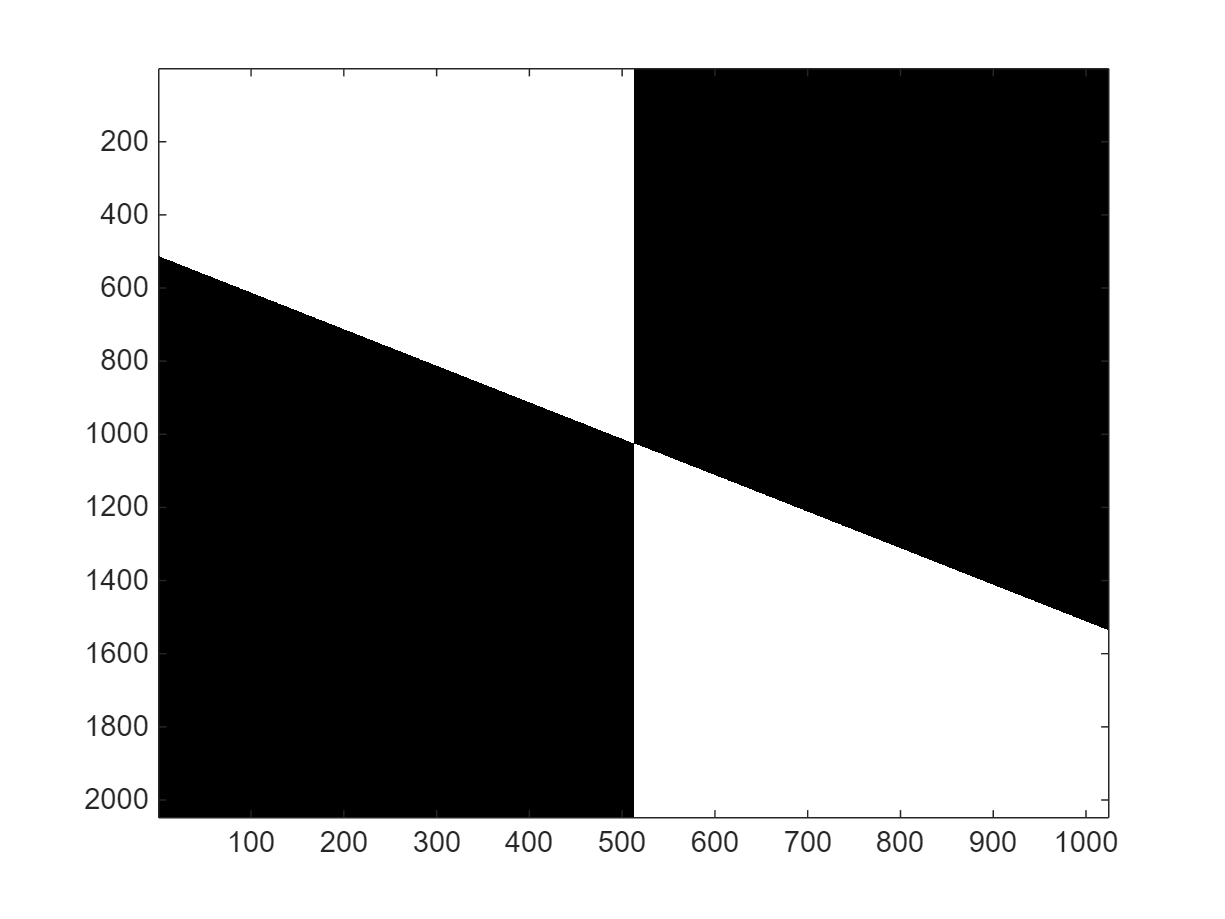



c_mask=[zeros(n,m),M(n:-1:1,:);M(:,m:-1:1),zeros(n,m)];
imagesc(c_mask(end:-1:1,:));

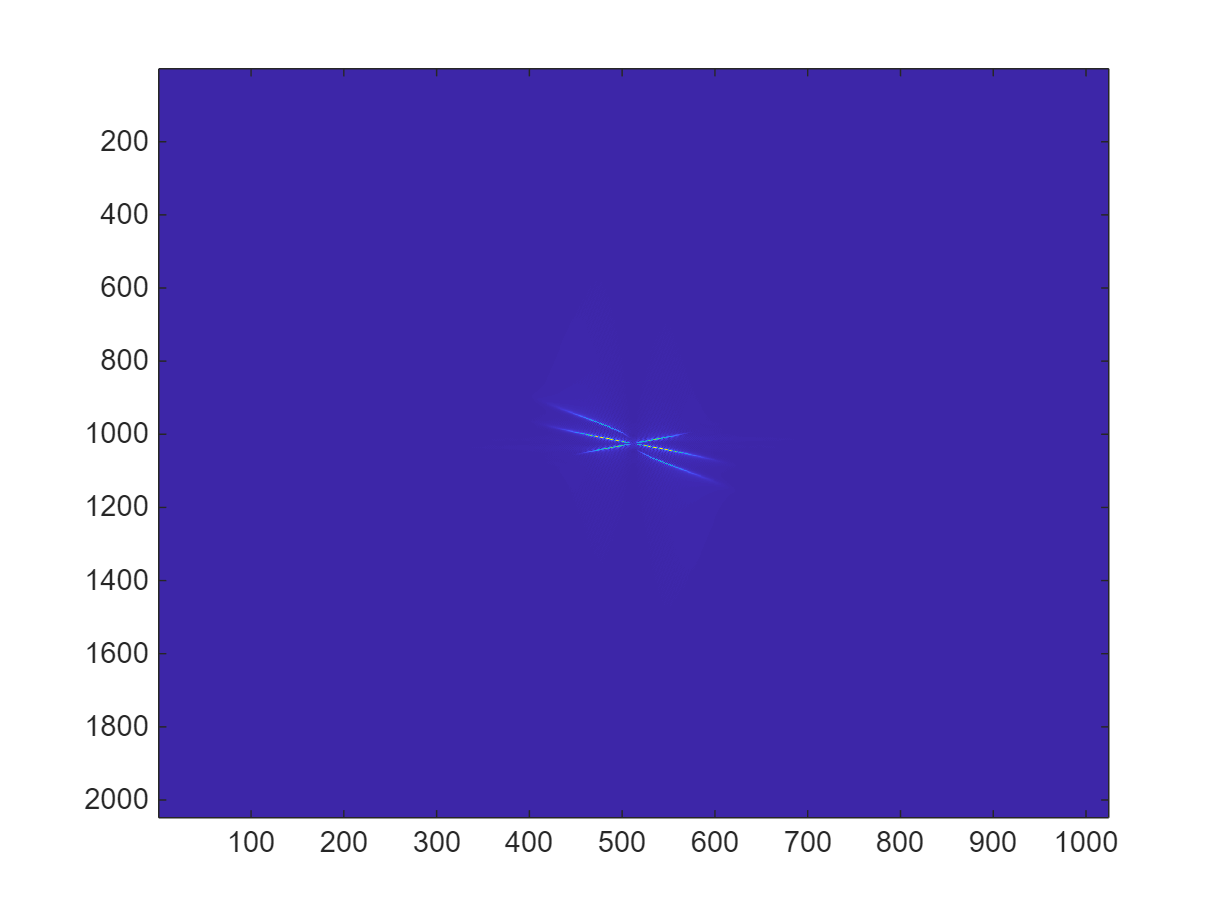

figure
imagesc(abs(X))

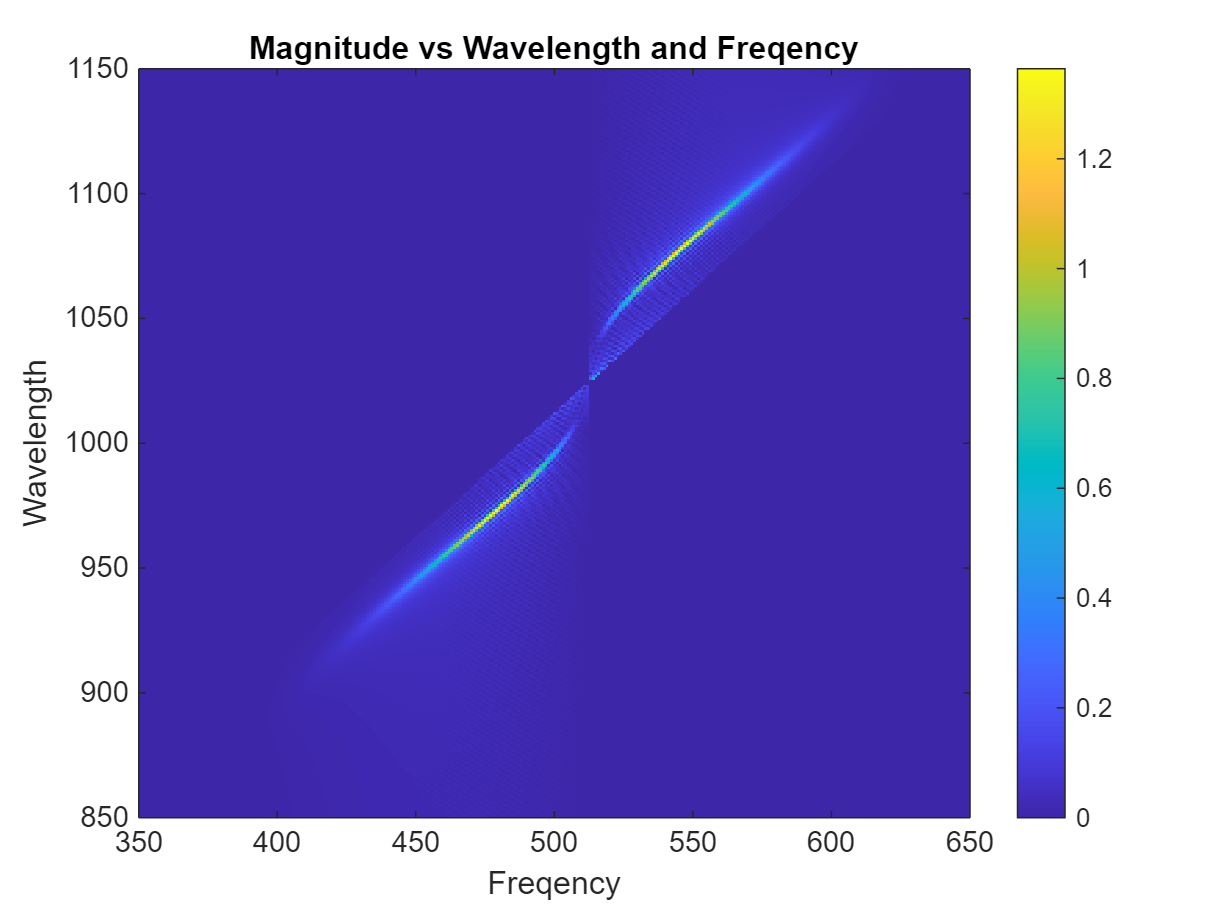

ans3=X.*c_mask(end:-1:1,:);
imagesc(abs(ans3))
axis xy
colorbar
xlim([350,650]);
ylim([850,1150]);
xlabel('Freqency')
ylabel('Wavelength')
title('Magnitude vs Wavelength and Freqency')

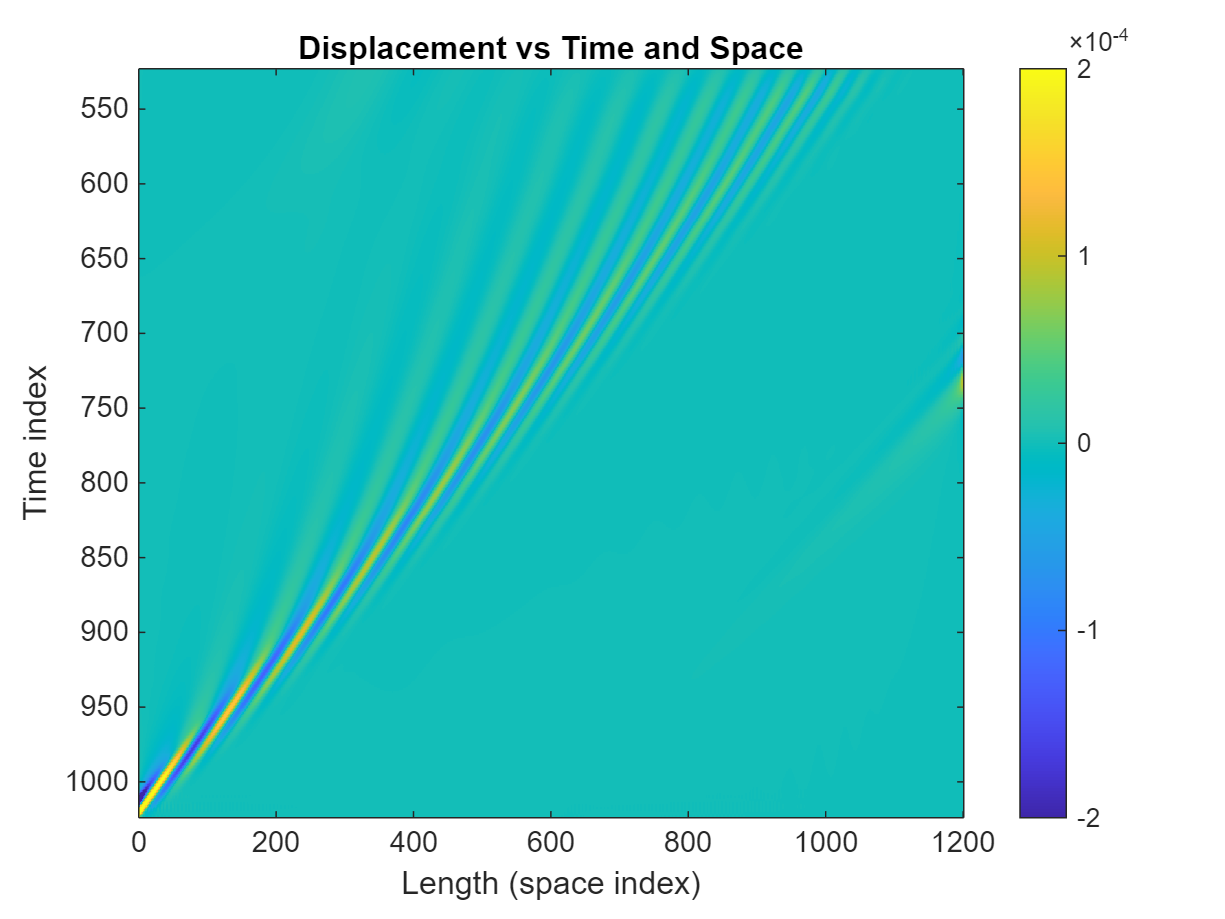

X_inv3 = ifftshift(ans3);   %
X_inv3 = flip(X_inv3, 2);
X_inv3 = X_inv3.';
u_rec3 = ifft2(X_inv3);
figure
imagesc(flip(real(u_rec3),2))
% axis xy
colorbar
clim([-2,2]/1e4)
xlim([0,1201])
ylim([1024-501,1024])
xlabel('Length (space index)')
ylabel('Time index')
title('Displacement vs Time and Space')